# Liniowe systemy dynamiczne: reprezentacje kanoniczne, sprzężenie zwrotne od stanu, rozmieszczanie biegunów

Krzysztof Arent

2024

## laboratorium

#### imię i nazwisko studenta: Kacper Karkosz i Aleksander Łyskawa

### Zadanie 1

Rozważmy dwie reprezentacje liniowego systemu dynamicznego ze zmiennymi stanu


$$\dot{x}_1=A_1 x_1 + B_1u \\
y=C_1 x_1$$
 
$$\quad (1)$$


oraz


$$\dot{x}_2=A_2 x_2 + B_2 u \\
y= C_2 x_2$$
 
$$\quad (2)$$


gdzie $x_2=S^{-1} x_1$, $A_2=S^{-1} A_1 S$, $B_2=S^{-1} B_1$, $C_2=C S_1$ a $S$ jest nieosobliwą macierzą kwadratową. Reprezentacje (1) i (2) nazywamy wejściowo-wyjściowo równoważnymi. Z perspektywy wejścia i wyjścia takie reprezentacje są identyczne ale z punktu widzenia ich parametrów (macierzy $A, ~B, ~C, ~D $) jedne mogą być bardziej atrakcyjne inne mniej w kontekście rozważań teoretycznych czy badań własności systemu.

Celem tego zadania jest nabycie pewnych intuicji dotyczących reprezentacji systemu wejście/stan/wyjście, które są wejściowo-wyjściowo równoważne.

Niech $A_1=$$\left\lbrack \begin{array}{ccc}
0 & 0 & -a_0 \\
1 & 0 & -a_1 \\
0 & 1 & -a_2 
\end{array}\right\rbrack$, $B_1=$$\left\lbrack \begin{array}{c}
b_0 \\
b_1 \\
b_2 
\end{array}\right\rbrack$, $C_1=$$\left\lbrack \begin{array}{ccc}
0 & 0 & 1
\end{array}\right\rbrack \ldotp$ Przyąć $a_0=6, ~a_1=11, ~a_2=6$, $b_0=20, ~b_1=9, ~b_2=1$. $S \in \mathbb{R}^{3 \times 3}$ jest macierzą nieosobliwą, której elementy mają wartości losowe. 

- Sprawdzić, że w rozważanym przypadku, jeżeli w (1) i (2) pobudzenie $u(t)=\cos(\frac{1}{3}t)$, stan początkowy $x(0)$ ma elementy o wartościach losowych, $x_2(0)=S^{-1} x_1(0)$ to sygnały wyjściowe $y(t)$ w (1) i (2) są identyczne dla wszystkich $t \geq 0$.

- Sprawdzić, że transmitancje operatorowe stowarzyszone z (1) i (2) są sobie równe.

Powyższe zadanie można zrealizować w sposób następujący:

clear all
close all

% zmiana bazy w przestrzeni stanu, równoważne reprezentacje ze zmiennymi
% stanu, macierze podobne

% macierze systemu (1)
A1=[0,0,-6; 1,0,-11; 0,1,-6]

A1 =      0     0    -6
     1     0   -11
     0     1    -6


B1=[20;9;1]

B1 =     20
     9
     1


C1=[0,0,1]

C1 =      0     0     1


D1=0

D1 = 0

% obiekt reprezentujący system dynamiczny ze zmiennymi stanu wyznaczony
% przez macierze A1, B1, C1, D1
s1=ss(A1,B1,C1,D1); 
% macierze systemu (2) otrzymane na podstawie macierzy systemu (1)
S=rand(3,3)

S =     0.8491    0.7577    0.6555
    0.9340    0.7431    0.1712
    0.6787    0.3922    0.7060


A2=inv(S)*A1*S

A2 =    -9.6568   -4.2875  -13.1201
    2.4291    0.2046    6.1256
    3.4887    1.7274    3.4522


B2=inv(S)*B1

B2 =   -55.3793
   79.2674
   10.6184


C2=C1*S

C2 =     0.6787    0.3922    0.7060


D2=D1

D2 = 0

% obiekt reprezentujący system dynamiczny ze zmiennymi stanu wyznaczony
% przez macierze A2, B2, C2, D2
s2=ss(A2,B2,C2,D2);

#### (1) podobieństwo reakcji y na to samo pobudzenie u w przypadku obydwu reprezentacji

% 
x01=rand(3,1)

x01 =     0.0318
    0.2769
    0.0462


x02=inv(S)*x01

x02 =     0.6944
   -0.4144
   -0.3719


T=[0,20];
[u_sin,T_sin] = gensig("sine",2*pi*3,T(end));
[y1_sin, Tout1, x1_sin]=lsim(s1,u_sin,T_sin, x01);
[y2_sin, Tout2, x2_sin]=lsim(s2,u_sin,T_sin, x02);
if all(abs(y1_sin-y2_sin) < 1e-14)
    disp('y1_sin==y2_sin  :)')
else
    disp('y1_sin~=y2_sin  :(')
end

y1_sin~=y2_sin  :(


plot(Tout1, y1_sin, 'blue')
hold on
plot(Tout2, y2_sin, 'red')
xlabel('t'), ylabel('y_1, y_2')
hold off

#### (2) podobieństwo transmitancji operatorowych

%
% obiekt reprezentujący system dynamiczny w formie transmitancji
% operatorowej utworzony na bazie obiektu s1
G1=tf(s1)

G1 =
 
      s^2 + 9 s + 20
  ----------------------
  s^3 + 6 s^2 + 11 s + 6
 
Continuous-time transfer function.
Model Properties


% obiekt reprezentujący system dynamiczny w formie transmitancji
% operatorowej utworzony na bazie obiektu s2
G2=tf(s2)

G2 =
 
      s^2 + 9 s + 20
  ----------------------
  s^3 + 6 s^2 + 11 s + 6
 
Continuous-time transfer function.
Model Properties


% test podobieństwa transmitancji G1 i G2
if all(abs(G1.Numerator{1}-G2.Numerator{1}) < 1e-12) && all(abs(G1.Denominator{1}-G2.Denominator{1}) < 1e-12)
    disp('G1(s)==G2(s)  :)')
else
    disp('G1(s)~=G2(s)  :(')
end

G1(s)==G2(s)  :)


Czy odpowiadające sobie elementy macierzy $A1 \mbox{ i } A2$, $B1 \mbox{ i } B2$, $C1 \mbox{ i } C2$ mają wartości praktycznie identyczne czy może są one istotnie różne?

**Odp.:** różne

Czy transmitancje operatorowe $G1$ i $G2$ są identyczne?

**Odp.:** TAK

Czy sygnały wyjściowe $y1\_sin$ i $y2\_sin$ są identyczne?

**Odp.:** NIE

Powtórzyć powyższe zadanie dla $a_0=1.875, ~a_1=5.75, ~a_2=4.5$, $b_0=0.1875, ~b_1=1, ~b_2=1$

% Wpisz tutaj odpowiedni kod w Matlabie, którego wykonanie dostarczy rozwiązania
% powyżej postawionego zadania.

clear all
close all

% zmiana bazy w przestrzeni stanu, równoważne reprezentacje ze zmiennymi
% stanu, macierze podobne

% macierze systemu (1)
A1=[0,0,-1.875; 1,0,-5.75; 0,1,-4.5]

A1 =          0         0   -1.8750
    1.0000         0   -5.7500
         0    1.0000   -4.5000


B1=[0.1875;1;1]

B1 =     0.1875
    1.0000
    1.0000


C1=[0,0,1]

C1 =      0     0     1


D1=0

D1 = 0

% obiekt reprezentujący system dynamiczny ze zmiennymi stanu wyznaczony
% przez macierze A1, B1, C1, D1
s1=ss(A1,B1,C1,D1); 
% macierze systemu (2) otrzymane na podstawie macierzy systemu (1)
S=rand(3,3)

S =     0.0971    0.3171    0.4387
    0.8235    0.9502    0.3816
    0.6948    0.0344    0.7655


A2=inv(S)*A1*S

A2 =    -1.9722    0.9532   -2.4201
   -1.9389   -0.7847   -1.3734
   -1.1314    0.2089   -1.7431


B2=inv(S)*B1

B2 =     1.2037
   -0.0780
    0.2172


C2=C1*S

C2 =     0.6948    0.0344    0.7655


D2=D1

D2 = 0

% obiekt reprezentujący system dynamiczny ze zmiennymi stanu wyznaczony
% przez macierze A2, B2, C2, D2
s2=ss(A2,B2,C2,D2);

% 
x01=rand(3,1)

x01 =     0.7952
    0.1869
    0.4898


x02=inv(S)*x01

x02 =    -1.1756
    0.5398
    1.6826


T=[0,20];
[u_sin,T_sin] = gensig("sine",2*pi*3,T(end));
[y1_sin, Tout1, x1_sin]=lsim(s1,u_sin,T_sin, x01);
[y2_sin, Tout2, x2_sin]=lsim(s2,u_sin,T_sin, x02);
if all(abs(y1_sin-y2_sin) < 1e-14)
    disp('y1_sin==y2_sin  :)')
else
    disp('y1_sin~=y2_sin  :(')
end

y1_sin==y2_sin  :)


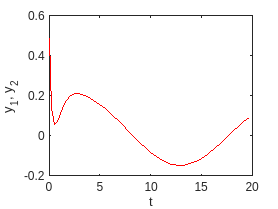

plot(Tout1, y1_sin, 'blue')
hold on
plot(Tout2, y2_sin, 'red')
xlabel('t'), ylabel('y_1, y_2')
hold off

Czy wnioski wynikające z zadania ze zmienionymi parametrami są identyczne jak w przypadku wcześniejszym?

**Odp.: Nie, nie są**

### Zadanie 2

Rozważmy reprezentację liniowego systemu dynamicznego ze zmiennymi stanu, w którym sygnał sterujący ma postać liniowego sprzężenia zwrotnego od stanu:


$$\dot{x}=A x + Bu \\
u=F x$$
 
$$\quad (3)$$


Należy zbadać wpływ macierzy wzmocnienia $F$na stabilność układu (3) analizuąc rozwiązania numeryczne (3) dla wybranych wartości F.

Macierze $A$i $B$ mają mieć strukturę taką jak $A_1$ i $B_1$  w Zadaniu 1, przy czym $a_0=-6, ~a_1=11, ~a_2=-6$, $b_0=20, ~b_1=9, ~b_2=1$. Rozważymy dwa przypadki:

- 
$$F=[0 ~0 ~0]$$


- 
$$F=[-0.0429 ~-0.7571 ~-4.3286 ]$$


W pierwszym przypadku sygnał wejściowy $u$ nie ma wpływu na ewolucję stanu $x$ w czasie. W drugim przypadku taki wpływ jest.

Przed przystąpieniem do realizacji zadania sprawdzić, że układ równań (3) można przekształcić do następującej postaci:


$$\dot{x}=(A+BF)x \\ u=F x$$
 
$$\quad (4)$$


Układ równań (4) jest wygodniejszy z punktu widzenia badań symulacyjnych.

Powyższe zadanie można zrealizować w sposób następujący:

clear all
close all

A=[0,0,6; 1,0,-11; 0,1,6]
B=[20;9;1]
C=[0,0,1]
D=0
if rank(ctrb(A,B))==size(A,1)
    disp('sterowalność  :)')
else
    disp('sterowalność  :(')
end
if (all(real(eig(A))<0))
    disp('stabilnosc  :)')
else
    disp('stabilnosc  :(')
end

#### (1): F=0

% przypadek 1: F=0
% definicja sprzężenia zwrotnego od stanu
F=[0, 0, 0]
u=@(x)F*x;
% definicja obiektu reprezentującego układ sprzężenia zwrotnego (3) lub (4)
system=ode;
system.ODEFcn=@(t,x)(A*x+B*u(x))
system.InitialValue=[1;1;1]
system.InitialTime=0;
% numeryczne rozwiązanie układu równań (4)
rozwiazanie=solve(system,0,10)
plot(rozwiazanie.Time, rozwiazanie.Solution)
xlabel('t'), ylabel('x'), title('F=[0,0,0]') 

#### (2): F~=0

% przypadek 2: F~=0
% definicja sprzężenia zwrotnego od stanu
F=[-0.0429, -0.7571, -4.3286]
u=@(x)F*x;
% definicja obiektu reprezentującego układ sprzężenia zwrotnego (3) lub (4)
system=ode;
system.ODEFcn=@(t,x)(A*x+B*u(x))
system.InitialValue=[1;1;1]
system.InitialTime=0;
% numeryczne rozwiązanie układu równań (4)
rozwiazanie=solve(system,0,10)
plot(rozwiazanie.Time, rozwiazanie.Solution)
xlabel('t'), ylabel('x'), title('F=[-0.0429, -0.7571, -4.3286]') 

Czy można ustabilizować system (3) dobierając odpowiednie wartości macierzy wzmocnienia F w sprzężeniu zwrotnym of stanu?

**Odp:** TAK/NIE

Wykonać analogiczne testy dla $a_0=-1.8750, ~a_1=5.75, ~a_2=-4.5$, $b_0=0.1875, ~b_1=-1, ~b_2=1$.

- 
$$F=[0 ~0 ~0]$$


- 
$$F=[34.6667  ~22.6667   ~8.6667]$$


% Wpisz tutaj odpowiedni kod w Matlabie, którego wykonanie dostarczy rozwiązania
% powyżej postawionego zadania.

Czy powyższe badanie potwierdza wcześniej wyciągnięte wnioski?

**Odp.**: TAK/NIE

### Zadanie 3

Obecnie zajmiemy się dwiema reprezentacjami systemów wejście/stan/wyjście: w kanonicznej postaci sterowalnej i w kanonicznej postaci regulatorowej, do których można przekształcić każdy system wejście/stan/wyjście typu SISO, który jest sterowalny. Obydwie reprezentacje mają szereg użytecznych własności, zebranych poniżej.

Rozważmy równania wejścia-stan w układach (1) i (2). Przyjmiemy założenie, że system (1) jest sterowalny, tzn. $\mbox{rank} [B_1 ~A_1 B_1 ~A_1^2B_1 ~\ldots~ A_1^{n-1} B_1]=n$ gdzie $n$jest wymiarem prestrzeni stanu. Niech $a(s)=s^{n}+a_{n-1} s^{n-1}+ \ldots +a_0, \quad s \in \mathbb{C}$, będzie wielomianem charakterystycznym $A_1$ (tzn. $a(s)=\det (s I -A_1)$) i niech $G_1(s)=\frac{b_{n-1} s^{n-1} + b_{1} s +b_0}{ s^{n}+a_{n-1} s^{n-1} + a_{1} s +a_0}:=C_1 (sI-A_1)^{-1}B_1$. 

Sprawdzić dla n=3, że 

- jeżeli $S=\Omega$ to $A_s:=A_2=S^{-1} A_1 S=$$\left\lbrack \begin{array}{ccc}
0 & 0 & -a_0 \\
1 & 0 & -a_1 \\
0 & 1 & {-a}_2 
\end{array}\right\rbrack$, $B_s:=B_2=S^{-1}B_1=$$\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack$, $C_s:=C_2=C_1 S=[c_0~ c_1 ~c_2]$ (macierze w kanonicznej postaci sterowalnej);

- jeżeli $S=\Omega W$, gdzie $W=$$\left\lbrack \begin{array}{ccc}
a_1  & a_2  & 1\\
a_2  & 1 & 0\\
1 & 0 & 0
\end{array}\right\rbrack$  to $A_r:=A_2=S^{-1} A_1 S=$$\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-a_0  & -a_1  & {-a}_2 
\end{array}\right\rbrack$, $B_r:=B_2=S^{-1}B_1=$$\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$, $C_r:=C_2=C S=[b_0 ~b_1 ~b_2]$ (macierze w kanonicznej postaci regulatorowej);

- $\det (sI-A_s)=\det (sI-A_r)=a(s)$;

- $A_s=A_r^T$;

- jeżeli $G(s)=C (sI-A) B, \quad G_s(s)=C_s (sI-A_s) B_s,  \quad G_r(s)=C_r (sI-A_r) B_r$ to $G(s)=G_r(s)=G_s(s)$

Powyższe zadanie można zrealizować w sposób następujący:


clear all
close all

% reprezentacja kanoniczna sterowalna i reprezentacja kanoniczna
% regulatorowa

n=3

n = 3


% deklaracja zmiennych i funkcji symbolicznych (obiektów klasy sym)
syms A1 [n,n]  % macierz stowarzyszona z równaniem (1)
syms B1 [n,1]  % macierz stowarzyszona z równaniem (1)
syms C1 [1,n]  % macierz stowarzyszona z równaniem (1)
syms s 
for i=1:n
    eval("syms "+"a"+string(i-1));  % zmienne a0, a1, ...
    eval("syms "+"b"+string(i-1));  % zmienne b0, b1, ...
end

zmienne_a={};  % tablica zmiennych a0, a1, ...
zmienne_b={};  % tablica zmiennych b0, b1, ...
for i=1:n
    zmienne_a=[zmienne_a, eval("a"+string(i-1))];
    zmienne_b=[zmienne_b, eval("b"+string(i-1))];
end

% A1_wch - wielomian charakterystyczny macierzy A1 
% (przyrostek wch oznacza wielomian charakterystyczny)
A1_wch=det(s*eye(n)-A1)

$$A1\_wch = s^{3}-A_{12,2}\,s^{2}-A_{13,3}\,s^{2}-A_{11,1}\,s^{2}-A_{11,1}\,A_{12,2}\,A_{13,3}+A_{11,1}\,A_{12,3}\,A_{13,2}+A_{11,2}\,A_{12,1}\,A_{13,3}-A_{11,2}\,A_{12,3}\,A_{13,1}-A_{11,3}\,A_{12,1}\,A_{13,2}+A_{11,3}\,A_{12,2}\,A_{13,1}+A_{11,1}\,A_{12,2}\,s-A_{11,2}\,A_{12,1}\,s+A_{11,1}\,A_{13,3}\,s-A_{11,3}\,A_{13,1}\,s+A_{12,2}\,A_{13,3}\,s-A_{12,3}\,A_{13,2}\,s$$

% A1_wch_wsp - tablica współczynników wielomianu charakterystycznego A1
% (przyrostek wsp oznacza współczynniki)
A1_wch_wsp=coeffs(A1_wch,s)

$$A1\_wch\_wsp = \left(\begin{array}{cccc} A_{11,1}\,A_{12,3}\,A_{13,2}-A_{11,1}\,A_{12,2}\,A_{13,3}+A_{11,2}\,A_{12,1}\,A_{13,3}-A_{11,2}\,A_{12,3}\,A_{13,1}-A_{11,3}\,A_{12,1}\,A_{13,2}+A_{11,3}\,A_{12,2}\,A_{13,1} & A_{11,1}\,A_{12,2}-A_{11,2}\,A_{12,1}+A_{11,1}\,A_{13,3}-A_{11,3}\,A_{13,1}+A_{12,2}\,A_{13,3}-A_{12,3}\,A_{13,2} & -A_{11,1}-A_{12,2}-A_{13,3} & 1 \end{array}\right)$$

% sprawdzamy, czy
% A1_wch_wsp(1)*1+A1_wch_wsp(2)*s+A1_wch_wsp(3)*s^2+A1_wch_wsp(4)*s^3 + ... jest
% równy A1_wch
if simplify(sum((s.^(0:1:n)).*A1_wch_wsp) - A1_wch)==0
    disp('A1_wch, A1_wch_wsp  :)');
else
    disp('A1_wch, A1_wch_wsp  :(');
end

A1_wch, A1_wch_wsp  :)


% tworzymy macierz Kalmana stowarzyszoną z A1, B1 o nazwie Omega ([B1 A1*B1, ..., A1^(n-1)*B1]).
% milczące założenie: parametry A1, B1 są takie, że det Omega ~= 0
Omega=B1

$$Omega = \left(\begin{array}{c} B_{11}\\ B_{12}\\ B_{13} \end{array}\right)$$

for i=1:n-1
    Omega=[B1 A1*Omega];
end

#### 1) kanoniczna postać sterowalna

% kanoniczna postać sterowalna

% dokonujemy przekształcenia z (A1, B1, C3, D1) do (A2, B2, C2, D2) jak w
% (1) i (2), przy czym eraz A2=As, B2=Bs, C2=Cs, D2=Ds
S=Omega

$$S = \begin{array}{l} \left(\begin{array}{ccc} B_{11} & \sigma_{3} & A_{11,1}\,\sigma_{3}+A_{11,2}\,\sigma_{2}+A_{11,3}\,\sigma_{1}\\ B_{12} & \sigma_{2} & A_{12,1}\,\sigma_{3}+A_{12,2}\,\sigma_{2}+A_{12,3}\,\sigma_{1}\\ B_{13} & \sigma_{1} & A_{13,1}\,\sigma_{3}+A_{13,2}\,\sigma_{2}+A_{13,3}\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=A_{13,1}\,B_{11}+A_{13,2}\,B_{12}+A_{13,3}\,B_{13}\\ \sigma_{2}=A_{12,1}\,B_{11}+A_{12,2}\,B_{12}+A_{12,3}\,B_{13}\\ \sigma_{3}=A_{11,1}\,B_{11}+A_{11,2}\,B_{12}+A_{11,3}\,B_{13} \end{array}$$

As=simplify(inv(S)*A1*S)

$$As = \left(\begin{array}{ccc} 0 & 0 & A_{11,1}\,A_{12,2}\,A_{13,3}-A_{11,1}\,A_{12,3}\,A_{13,2}-A_{11,2}\,A_{12,1}\,A_{13,3}+A_{11,2}\,A_{12,3}\,A_{13,1}+A_{11,3}\,A_{12,1}\,A_{13,2}-A_{11,3}\,A_{12,2}\,A_{13,1}\\ 1 & 0 & A_{11,2}\,A_{12,1}-A_{11,1}\,A_{12,2}-A_{11,1}\,A_{13,3}+A_{11,3}\,A_{13,1}-A_{12,2}\,A_{13,3}+A_{12,3}\,A_{13,2}\\ 0 & 1 & A_{11,1}+A_{12,2}+A_{13,3} \end{array}\right)$$

Bs=simplify(inv(S)*B1)

$$Bs = \left(\begin{array}{c} 1\\ 0\\ 0 \end{array}\right)$$

Cs=simplify(C1*S)

$$Cs = \begin{array}{l} \left(\begin{array}{ccc} B_{11}\,C_{11}+B_{12}\,C_{12}+B_{13}\,C_{13} & C_{11}\,\sigma_{3}+C_{12}\,\sigma_{2}+C_{13}\,\sigma_{1} & C_{11}\,\left(A_{11,1}\,\sigma_{3}+A_{11,2}\,\sigma_{2}+A_{11,3}\,\sigma_{1}\right)+C_{12}\,\left(A_{12,1}\,\sigma_{3}+A_{12,2}\,\sigma_{2}+A_{12,3}\,\sigma_{1}\right)+C_{13}\,\left(A_{13,1}\,\sigma_{3}+A_{13,2}\,\sigma_{2}+A_{13,3}\,\sigma_{1}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=A_{13,1}\,B_{11}+A_{13,2}\,B_{12}+A_{13,3}\,B_{13}\\ \sigma_{2}=A_{12,1}\,B_{11}+A_{12,2}\,B_{12}+A_{12,3}\,B_{13}\\ \sigma_{3}=A_{11,1}\,B_{11}+A_{11,2}\,B_{12}+A_{11,3}\,B_{13} \end{array}$$


% sprawdzenie, że wielomiany charakterystyczne A1 i As są identyczne
As_wch=simplify(det(s*eye(n)-As));
if simplify(A1_wch-As_wch)==0
    disp('A1_wch==wchAs  :)');
else
    disp('A1_wch~=wchAs:(');
end

A1_wch==wchAs  :)



% sprawdzenie, że współczynniki wielomianu charakterystycznego As jawnie 
% występują w macierzy As (w ostatniej kolumnie)
for i=1:n
    if -As(i,n)==A1_wch_wsp(1,i)
        disp('A1_wch_wsp w As  :)');
    else
        disp('A1_wch_wsp w As  :(');
    end
end

A1_wch_wsp w As  :)
A1_wch_wsp w As  :)
A1_wch_wsp w As  :)


Czy stwierdzenie nr 1 jest prawdziwe?

**Odp.: **TAK/NIE

#### (2) kanoniczna postać regulatorowa

% kanoniczna postać regulatorowa

% dokonujemy przekształcenia z (A1, B1, C3, D1) do (A2, B2, C2, D2) jak w
% (1) i (2), przy czym eraz A2=As, B2=Bs, C2=Cs, D2=Ds

% macierz W z punktu 2 w zadaniu 3
W=A1_wch_wsp(2:n+1)

$$W = \left(\begin{array}{ccc} A_{11,1}\,A_{12,2}-A_{11,2}\,A_{12,1}+A_{11,1}\,A_{13,3}-A_{11,3}\,A_{13,1}+A_{12,2}\,A_{13,3}-A_{12,3}\,A_{13,2} & -A_{11,1}-A_{12,2}-A_{13,3} & 1 \end{array}\right)$$

for i=1:n-1
    W=[W; [A1_wch_wsp(2+i:n+1) zeros(1:i)] ]; 
end
S=Omega*W

$$S = \begin{array}{l} \left(\begin{array}{ccc} B_{11}\,\sigma_{1}-\sigma_{4}\,\left(A_{11,1}+A_{12,2}+A_{13,3}\right)+A_{11,1}\,\sigma_{4}+A_{11,2}\,\sigma_{3}+A_{11,3}\,\sigma_{2} & A_{11,1}\,B_{11}-B_{11}\,\left(A_{11,1}+A_{12,2}+A_{13,3}\right)+A_{11,2}\,B_{12}+A_{11,3}\,B_{13} & B_{11}\\ B_{12}\,\sigma_{1}-\sigma_{3}\,\left(A_{11,1}+A_{12,2}+A_{13,3}\right)+A_{12,1}\,\sigma_{4}+A_{12,2}\,\sigma_{3}+A_{12,3}\,\sigma_{2} & A_{12,1}\,B_{11}-B_{12}\,\left(A_{11,1}+A_{12,2}+A_{13,3}\right)+A_{12,2}\,B_{12}+A_{12,3}\,B_{13} & B_{12}\\ B_{13}\,\sigma_{1}-\sigma_{2}\,\left(A_{11,1}+A_{12,2}+A_{13,3}\right)+A_{13,1}\,\sigma_{4}+A_{13,2}\,\sigma_{3}+A_{13,3}\,\sigma_{2} & A_{13,1}\,B_{11}-B_{13}\,\left(A_{11,1}+A_{12,2}+A_{13,3}\right)+A_{13,2}\,B_{12}+A_{13,3}\,B_{13} & B_{13} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=A_{11,1}\,A_{12,2}-A_{11,2}\,A_{12,1}+A_{11,1}\,A_{13,3}-A_{11,3}\,A_{13,1}+A_{12,2}\,A_{13,3}-A_{12,3}\,A_{13,2}\\ \sigma_{2}=A_{13,1}\,B_{11}+A_{13,2}\,B_{12}+A_{13,3}\,B_{13}\\ \sigma_{3}=A_{12,1}\,B_{11}+A_{12,2}\,B_{12}+A_{12,3}\,B_{13}\\ \sigma_{4}=A_{11,1}\,B_{11}+A_{11,2}\,B_{12}+A_{11,3}\,B_{13} \end{array}$$

Ar=simplify(inv(S)*A1*S)

$$Ar = \left(\begin{array}{ccc} 0 & 1 & 0\\ 0 & 0 & 1\\ A_{11,1}\,A_{12,2}\,A_{13,3}-A_{11,1}\,A_{12,3}\,A_{13,2}-A_{11,2}\,A_{12,1}\,A_{13,3}+A_{11,2}\,A_{12,3}\,A_{13,1}+A_{11,3}\,A_{12,1}\,A_{13,2}-A_{11,3}\,A_{12,2}\,A_{13,1} & A_{11,2}\,A_{12,1}-A_{11,1}\,A_{12,2}-A_{11,1}\,A_{13,3}+A_{11,3}\,A_{13,1}-A_{12,2}\,A_{13,3}+A_{12,3}\,A_{13,2} & A_{11,1}+A_{12,2}+A_{13,3} \end{array}\right)$$

Br=simplify(inv(S)*B1)

$$Br = \left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

Cr=simplify(C1*S)

$$Cr = \left(\begin{array}{ccc} A_{11,1}\,A_{12,2}\,B_{13}\,C_{13}-A_{11,1}\,A_{12,3}\,B_{13}\,C_{12}-A_{11,2}\,A_{12,1}\,B_{13}\,C_{13}+A_{11,2}\,A_{12,3}\,B_{13}\,C_{11}+A_{11,3}\,A_{12,1}\,B_{13}\,C_{12}-A_{11,3}\,A_{12,2}\,B_{13}\,C_{11}-A_{11,1}\,A_{13,2}\,B_{12}\,C_{13}+A_{11,1}\,A_{13,3}\,B_{12}\,C_{12}+A_{11,2}\,A_{13,1}\,B_{12}\,C_{13}-A_{11,2}\,A_{13,3}\,B_{12}\,C_{11}-A_{11,3}\,A_{13,1}\,B_{12}\,C_{12}+A_{11,3}\,A_{13,2}\,B_{12}\,C_{11}+A_{12,1}\,A_{13,2}\,B_{11}\,C_{13}-A_{12,1}\,A_{13,3}\,B_{11}\,C_{12}-A_{12,2}\,A_{13,1}\,B_{11}\,C_{13}+A_{12,2}\,A_{13,3}\,B_{11}\,C_{11}+A_{12,3}\,A_{13,1}\,B_{11}\,C_{12}-A_{12,3}\,A_{13,2}\,B_{11}\,C_{11} & C_{11}\,\left(A_{11,1}\,B_{11}-B_{11}\,\left(A_{11,1}+A_{12,2}+A_{13,3}\right)+A_{11,2}\,B_{12}+A_{11,3}\,B_{13}\right)+C_{12}\,\left(A_{12,1}\,B_{11}-B_{12}\,\left(A_{11,1}+A_{12,2}+A_{13,3}\right)+A_{12,2}\,B_{12}+A_{12,3}\,B_{13}\right)+C_{13}\,\left(A_{13,1}\,B_{11}-B_{13}\,\left(A_{11,1}+A_{12,2}+A_{13,3}\right)+A_{13,2}\,B_{12}+A_{13,3}\,B_{13}\right) & B_{11}\,C_{11}+B_{12}\,C_{12}+B_{13}\,C_{13} \end{array}\right)$$

Czy stwierdzenie nr 2 jest prawdziwe?

**Odp.: **TAK/NIE

#### (3) wielomiany charakterystyczne As i Ar, ich związek z wielomianem charakterystycznym A1

% sprawdzenie, że wielomiany charakterystyczne A1 i Ar są identyczne
Ar_wch=simplify(det(s*eye(n)-Ar))

$$Ar\_wch = s^{3}-A_{12,2}\,s^{2}-A_{13,3}\,s^{2}-A_{11,1}\,s^{2}-A_{11,1}\,A_{12,2}\,A_{13,3}+A_{11,1}\,A_{12,3}\,A_{13,2}+A_{11,2}\,A_{12,1}\,A_{13,3}-A_{11,2}\,A_{12,3}\,A_{13,1}-A_{11,3}\,A_{12,1}\,A_{13,2}+A_{11,3}\,A_{12,2}\,A_{13,1}+A_{11,1}\,A_{12,2}\,s-A_{11,2}\,A_{12,1}\,s+A_{11,1}\,A_{13,3}\,s-A_{11,3}\,A_{13,1}\,s+A_{12,2}\,A_{13,3}\,s-A_{12,3}\,A_{13,2}\,s$$

if simplify(A1_wch-Ar_wch)==0
    disp('A1_wch==wchAr  :)');
else
    disp('A1_wch==wchAr  :(');
end

A1_wch==wchAr  :)



% sprawdzenie, że współczynniki wielomianu charakterystycznego A1 jawnie 
% występują w macierzy Ar (elementy Ar w najniższym wierszu)

for i=1:n
    if -Ar(n,i)==A1_wch_wsp(1,i)
        disp('A1_wch_wsp w Ar  :)');
    else
        disp('A1_wch_wsp w Ar  :(');
    end
end

A1_wch_wsp w Ar  :)
A1_wch_wsp w Ar  :)
A1_wch_wsp w Ar  :)


Czy stwierdzenie nr 3 jest prawdziwe?

**Odp.: **TAK/NIE

#### (4) wzajemne zależności pomiędzy As i Ar (As'==Ar), Bs i Br

% wzajemne zależności pomiędzy As i Ar
if all(all(logical(As.'==Ar)))
    disp(':)')
else
    disp(':(')
end

:)


% wzajemne zależności pomiędzy Bs i Br
if all(logical(flip(Bs)==Br))
    disp(':)')
else
    disp(':(')
end

:)


Czy stwierdzenie nr 4 jest prawdziwe?

**Odp.: **TAK/NIE

#### (5) G(s)=Gs(s)=Gr(s) i związek współczynników w transmitancjach z macierzami Ar, Br, Cr, As, Bs, Cs

% transmitancje operatorowe obydwu reprezentacji kanonicznych są sobie
% równe
Gr=simplify(Cr*(s*eye(n)-Ar)^(-1)*Br)

$$Gr = -\frac{B_{11}\,C_{11}\,s^{2}+B_{12}\,C_{12}\,s^{2}+B_{13}\,C_{13}\,s^{2}+A_{11,1}\,A_{12,2}\,B_{13}\,C_{13}-A_{11,1}\,A_{12,3}\,B_{13}\,C_{12}-A_{11,2}\,A_{12,1}\,B_{13}\,C_{13}+A_{11,2}\,A_{12,3}\,B_{13}\,C_{11}+A_{11,3}\,A_{12,1}\,B_{13}\,C_{12}-A_{11,3}\,A_{12,2}\,B_{13}\,C_{11}-A_{11,1}\,A_{13,2}\,B_{12}\,C_{13}+A_{11,1}\,A_{13,3}\,B_{12}\,C_{12}+A_{11,2}\,A_{13,1}\,B_{12}\,C_{13}-A_{11,2}\,A_{13,3}\,B_{12}\,C_{11}-A_{11,3}\,A_{13,1}\,B_{12}\,C_{12}+A_{11,3}\,A_{13,2}\,B_{12}\,C_{11}+A_{12,1}\,A_{13,2}\,B_{11}\,C_{13}-A_{12,1}\,A_{13,3}\,B_{11}\,C_{12}-A_{12,2}\,A_{13,1}\,B_{11}\,C_{13}+A_{12,2}\,A_{13,3}\,B_{11}\,C_{11}+A_{12,3}\,A_{13,1}\,B_{11}\,C_{12}-A_{12,3}\,A_{13,2}\,B_{11}\,C_{11}-A_{11,1}\,B_{12}\,C_{12}\,s+A_{11,2}\,B_{12}\,C_{11}\,s-A_{11,1}\,B_{13}\,C_{13}\,s+A_{11,3}\,B_{13}\,C_{11}\,s+A_{12,1}\,B_{11}\,C_{12}\,s-A_{12,2}\,B_{11}\,C_{11}\,s-A_{12,2}\,B_{13}\,C_{13}\,s+A_{12,3}\,B_{13}\,C_{12}\,s+A_{13,1}\,B_{11}\,C_{13}\,s-A_{13,3}\,B_{11}\,C_{11}\,s+A_{13,2}\,B_{12}\,C_{13}\,s-A_{13,3}\,B_{12}\,C_{12}\,s}{A_{11,1}\,s^{2}+A_{12,2}\,s^{2}+A_{13,3}\,s^{2}-s^{3}+A_{11,1}\,A_{12,2}\,A_{13,3}-A_{11,1}\,A_{12,3}\,A_{13,2}-A_{11,2}\,A_{12,1}\,A_{13,3}+A_{11,2}\,A_{12,3}\,A_{13,1}+A_{11,3}\,A_{12,1}\,A_{13,2}-A_{11,3}\,A_{12,2}\,A_{13,1}-A_{11,1}\,A_{12,2}\,s+A_{11,2}\,A_{12,1}\,s-A_{11,1}\,A_{13,3}\,s+A_{11,3}\,A_{13,1}\,s-A_{12,2}\,A_{13,3}\,s+A_{12,3}\,A_{13,2}\,s}$$

Gs=simplify(Cs*(s*eye(n)-As)^(-1)*Bs)

$$Gs = -\frac{B_{11}\,C_{11}\,s^{2}+B_{12}\,C_{12}\,s^{2}+B_{13}\,C_{13}\,s^{2}+A_{11,1}\,A_{12,2}\,B_{13}\,C_{13}-A_{11,1}\,A_{12,3}\,B_{13}\,C_{12}-A_{11,2}\,A_{12,1}\,B_{13}\,C_{13}+A_{11,2}\,A_{12,3}\,B_{13}\,C_{11}+A_{11,3}\,A_{12,1}\,B_{13}\,C_{12}-A_{11,3}\,A_{12,2}\,B_{13}\,C_{11}-A_{11,1}\,A_{13,2}\,B_{12}\,C_{13}+A_{11,1}\,A_{13,3}\,B_{12}\,C_{12}+A_{11,2}\,A_{13,1}\,B_{12}\,C_{13}-A_{11,2}\,A_{13,3}\,B_{12}\,C_{11}-A_{11,3}\,A_{13,1}\,B_{12}\,C_{12}+A_{11,3}\,A_{13,2}\,B_{12}\,C_{11}+A_{12,1}\,A_{13,2}\,B_{11}\,C_{13}-A_{12,1}\,A_{13,3}\,B_{11}\,C_{12}-A_{12,2}\,A_{13,1}\,B_{11}\,C_{13}+A_{12,2}\,A_{13,3}\,B_{11}\,C_{11}+A_{12,3}\,A_{13,1}\,B_{11}\,C_{12}-A_{12,3}\,A_{13,2}\,B_{11}\,C_{11}-A_{11,1}\,B_{12}\,C_{12}\,s+A_{11,2}\,B_{12}\,C_{11}\,s-A_{11,1}\,B_{13}\,C_{13}\,s+A_{11,3}\,B_{13}\,C_{11}\,s+A_{12,1}\,B_{11}\,C_{12}\,s-A_{12,2}\,B_{11}\,C_{11}\,s-A_{12,2}\,B_{13}\,C_{13}\,s+A_{12,3}\,B_{13}\,C_{12}\,s+A_{13,1}\,B_{11}\,C_{13}\,s-A_{13,3}\,B_{11}\,C_{11}\,s+A_{13,2}\,B_{12}\,C_{13}\,s-A_{13,3}\,B_{12}\,C_{12}\,s}{A_{11,1}\,s^{2}+A_{12,2}\,s^{2}+A_{13,3}\,s^{2}-s^{3}+A_{11,1}\,A_{12,2}\,A_{13,3}-A_{11,1}\,A_{12,3}\,A_{13,2}-A_{11,2}\,A_{12,1}\,A_{13,3}+A_{11,2}\,A_{12,3}\,A_{13,1}+A_{11,3}\,A_{12,1}\,A_{13,2}-A_{11,3}\,A_{12,2}\,A_{13,1}-A_{11,1}\,A_{12,2}\,s+A_{11,2}\,A_{12,1}\,s-A_{11,1}\,A_{13,3}\,s+A_{11,3}\,A_{13,1}\,s-A_{12,2}\,A_{13,3}\,s+A_{12,3}\,A_{13,2}\,s}$$

if simplify(Gr-Gs)==0
    disp('Gr(s)==Gs(s)  :)')
else
    disp('Gr(s)~=Gs(s)  :(')
end

Gr(s)==Gs(s)  :)


#### związek pomiędzy współczynnikami Gr a elementami Ar i Cr

% współczynniki licznika transmitancji Gr są elementami macierzy Cr
% współczynniki mianownika transmitancji Gr są elementami ostatniego
% wiersza macierzy Ar z odwróconymi znakami.

% wieloomiany w liczniku i w mianowniku transmitancji operatorowych Gr i Gs
[licznikGr, mianownikGr]=numden(Gr)

$$licznikGr = A_{11,1}\,A_{12,3}\,B_{13}\,C_{12}-B_{12}\,C_{12}\,s^{2}-B_{13}\,C_{13}\,s^{2}-A_{11,1}\,A_{12,2}\,B_{13}\,C_{13}-B_{11}\,C_{11}\,s^{2}+A_{11,2}\,A_{12,1}\,B_{13}\,C_{13}-A_{11,2}\,A_{12,3}\,B_{13}\,C_{11}-A_{11,3}\,A_{12,1}\,B_{13}\,C_{12}+A_{11,3}\,A_{12,2}\,B_{13}\,C_{11}+A_{11,1}\,A_{13,2}\,B_{12}\,C_{13}-A_{11,1}\,A_{13,3}\,B_{12}\,C_{12}-A_{11,2}\,A_{13,1}\,B_{12}\,C_{13}+A_{11,2}\,A_{13,3}\,B_{12}\,C_{11}+A_{11,3}\,A_{13,1}\,B_{12}\,C_{12}-A_{11,3}\,A_{13,2}\,B_{12}\,C_{11}-A_{12,1}\,A_{13,2}\,B_{11}\,C_{13}+A_{12,1}\,A_{13,3}\,B_{11}\,C_{12}+A_{12,2}\,A_{13,1}\,B_{11}\,C_{13}-A_{12,2}\,A_{13,3}\,B_{11}\,C_{11}-A_{12,3}\,A_{13,1}\,B_{11}\,C_{12}+A_{12,3}\,A_{13,2}\,B_{11}\,C_{11}+A_{11,1}\,B_{12}\,C_{12}\,s-A_{11,2}\,B_{12}\,C_{11}\,s+A_{11,1}\,B_{13}\,C_{13}\,s-A_{11,3}\,B_{13}\,C_{11}\,s-A_{12,1}\,B_{11}\,C_{12}\,s+A_{12,2}\,B_{11}\,C_{11}\,s+A_{12,2}\,B_{13}\,C_{13}\,s-A_{12,3}\,B_{13}\,C_{12}\,s-A_{13,1}\,B_{11}\,C_{13}\,s+A_{13,3}\,B_{11}\,C_{11}\,s-A_{13,2}\,B_{12}\,C_{13}\,s+A_{13,3}\,B_{12}\,C_{12}\,s$$

$$mianownikGr = A_{11,1}\,s^{2}+A_{12,2}\,s^{2}+A_{13,3}\,s^{2}-s^{3}+A_{11,1}\,A_{12,2}\,A_{13,3}-A_{11,1}\,A_{12,3}\,A_{13,2}-A_{11,2}\,A_{12,1}\,A_{13,3}+A_{11,2}\,A_{12,3}\,A_{13,1}+A_{11,3}\,A_{12,1}\,A_{13,2}-A_{11,3}\,A_{12,2}\,A_{13,1}-A_{11,1}\,A_{12,2}\,s+A_{11,2}\,A_{12,1}\,s-A_{11,1}\,A_{13,3}\,s+A_{11,3}\,A_{13,1}\,s-A_{12,2}\,A_{13,3}\,s+A_{12,3}\,A_{13,2}\,s$$

[licznikGs, mianownikGs]=numden(Gs)

$$licznikGs = A_{11,1}\,A_{12,3}\,B_{13}\,C_{12}-B_{12}\,C_{12}\,s^{2}-B_{13}\,C_{13}\,s^{2}-A_{11,1}\,A_{12,2}\,B_{13}\,C_{13}-B_{11}\,C_{11}\,s^{2}+A_{11,2}\,A_{12,1}\,B_{13}\,C_{13}-A_{11,2}\,A_{12,3}\,B_{13}\,C_{11}-A_{11,3}\,A_{12,1}\,B_{13}\,C_{12}+A_{11,3}\,A_{12,2}\,B_{13}\,C_{11}+A_{11,1}\,A_{13,2}\,B_{12}\,C_{13}-A_{11,1}\,A_{13,3}\,B_{12}\,C_{12}-A_{11,2}\,A_{13,1}\,B_{12}\,C_{13}+A_{11,2}\,A_{13,3}\,B_{12}\,C_{11}+A_{11,3}\,A_{13,1}\,B_{12}\,C_{12}-A_{11,3}\,A_{13,2}\,B_{12}\,C_{11}-A_{12,1}\,A_{13,2}\,B_{11}\,C_{13}+A_{12,1}\,A_{13,3}\,B_{11}\,C_{12}+A_{12,2}\,A_{13,1}\,B_{11}\,C_{13}-A_{12,2}\,A_{13,3}\,B_{11}\,C_{11}-A_{12,3}\,A_{13,1}\,B_{11}\,C_{12}+A_{12,3}\,A_{13,2}\,B_{11}\,C_{11}+A_{11,1}\,B_{12}\,C_{12}\,s-A_{11,2}\,B_{12}\,C_{11}\,s+A_{11,1}\,B_{13}\,C_{13}\,s-A_{11,3}\,B_{13}\,C_{11}\,s-A_{12,1}\,B_{11}\,C_{12}\,s+A_{12,2}\,B_{11}\,C_{11}\,s+A_{12,2}\,B_{13}\,C_{13}\,s-A_{12,3}\,B_{13}\,C_{12}\,s-A_{13,1}\,B_{11}\,C_{13}\,s+A_{13,3}\,B_{11}\,C_{11}\,s-A_{13,2}\,B_{12}\,C_{13}\,s+A_{13,3}\,B_{12}\,C_{12}\,s$$

$$mianownikGs = A_{11,1}\,s^{2}+A_{12,2}\,s^{2}+A_{13,3}\,s^{2}-s^{3}+A_{11,1}\,A_{12,2}\,A_{13,3}-A_{11,1}\,A_{12,3}\,A_{13,2}-A_{11,2}\,A_{12,1}\,A_{13,3}+A_{11,2}\,A_{12,3}\,A_{13,1}+A_{11,3}\,A_{12,1}\,A_{13,2}-A_{11,3}\,A_{12,2}\,A_{13,1}-A_{11,1}\,A_{12,2}\,s+A_{11,2}\,A_{12,1}\,s-A_{11,1}\,A_{13,3}\,s+A_{11,3}\,A_{13,1}\,s-A_{12,2}\,A_{13,3}\,s+A_{12,3}\,A_{13,2}\,s$$


% współczynniki wielomianów w licznikach i w mianownikach transmitancji
% operatorowych Gr i Gs
licznikGr_wsp=simplify(coeffs(licznikGr,s))

$$licznikGr\_wsp = \left(\begin{array}{ccc} A_{11,1}\,A_{12,3}\,B_{13}\,C_{12}-A_{11,1}\,A_{12,2}\,B_{13}\,C_{13}+A_{11,2}\,A_{12,1}\,B_{13}\,C_{13}-A_{11,2}\,A_{12,3}\,B_{13}\,C_{11}-A_{11,3}\,A_{12,1}\,B_{13}\,C_{12}+A_{11,3}\,A_{12,2}\,B_{13}\,C_{11}+A_{11,1}\,A_{13,2}\,B_{12}\,C_{13}-A_{11,1}\,A_{13,3}\,B_{12}\,C_{12}-A_{11,2}\,A_{13,1}\,B_{12}\,C_{13}+A_{11,2}\,A_{13,3}\,B_{12}\,C_{11}+A_{11,3}\,A_{13,1}\,B_{12}\,C_{12}-A_{11,3}\,A_{13,2}\,B_{12}\,C_{11}-A_{12,1}\,A_{13,2}\,B_{11}\,C_{13}+A_{12,1}\,A_{13,3}\,B_{11}\,C_{12}+A_{12,2}\,A_{13,1}\,B_{11}\,C_{13}-A_{12,2}\,A_{13,3}\,B_{11}\,C_{11}-A_{12,3}\,A_{13,1}\,B_{11}\,C_{12}+A_{12,3}\,A_{13,2}\,B_{11}\,C_{11} & A_{11,1}\,B_{12}\,C_{12}-A_{11,2}\,B_{12}\,C_{11}+A_{11,1}\,B_{13}\,C_{13}-A_{11,3}\,B_{13}\,C_{11}-A_{12,1}\,B_{11}\,C_{12}+A_{12,2}\,B_{11}\,C_{11}+A_{12,2}\,B_{13}\,C_{13}-A_{12,3}\,B_{13}\,C_{12}-A_{13,1}\,B_{11}\,C_{13}+A_{13,3}\,B_{11}\,C_{11}-A_{13,2}\,B_{12}\,C_{13}+A_{13,3}\,B_{12}\,C_{12} & -B_{11}\,C_{11}-B_{12}\,C_{12}-B_{13}\,C_{13} \end{array}\right)$$

mianownikGr_wsp=simplify(coeffs(mianownikGr,s))

$$mianownikGr\_wsp = \left(\begin{array}{cccc} A_{11,1}\,A_{12,2}\,A_{13,3}-A_{11,1}\,A_{12,3}\,A_{13,2}-A_{11,2}\,A_{12,1}\,A_{13,3}+A_{11,2}\,A_{12,3}\,A_{13,1}+A_{11,3}\,A_{12,1}\,A_{13,2}-A_{11,3}\,A_{12,2}\,A_{13,1} & A_{11,2}\,A_{12,1}-A_{11,1}\,A_{12,2}-A_{11,1}\,A_{13,3}+A_{11,3}\,A_{13,1}-A_{12,2}\,A_{13,3}+A_{12,3}\,A_{13,2} & A_{11,1}+A_{12,2}+A_{13,3} & -1 \end{array}\right)$$

licznikGs_wsp=simplify(coeffs(licznikGs,s))

$$licznikGs\_wsp = \left(\begin{array}{ccc} A_{11,1}\,A_{12,3}\,B_{13}\,C_{12}-A_{11,1}\,A_{12,2}\,B_{13}\,C_{13}+A_{11,2}\,A_{12,1}\,B_{13}\,C_{13}-A_{11,2}\,A_{12,3}\,B_{13}\,C_{11}-A_{11,3}\,A_{12,1}\,B_{13}\,C_{12}+A_{11,3}\,A_{12,2}\,B_{13}\,C_{11}+A_{11,1}\,A_{13,2}\,B_{12}\,C_{13}-A_{11,1}\,A_{13,3}\,B_{12}\,C_{12}-A_{11,2}\,A_{13,1}\,B_{12}\,C_{13}+A_{11,2}\,A_{13,3}\,B_{12}\,C_{11}+A_{11,3}\,A_{13,1}\,B_{12}\,C_{12}-A_{11,3}\,A_{13,2}\,B_{12}\,C_{11}-A_{12,1}\,A_{13,2}\,B_{11}\,C_{13}+A_{12,1}\,A_{13,3}\,B_{11}\,C_{12}+A_{12,2}\,A_{13,1}\,B_{11}\,C_{13}-A_{12,2}\,A_{13,3}\,B_{11}\,C_{11}-A_{12,3}\,A_{13,1}\,B_{11}\,C_{12}+A_{12,3}\,A_{13,2}\,B_{11}\,C_{11} & A_{11,1}\,B_{12}\,C_{12}-A_{11,2}\,B_{12}\,C_{11}+A_{11,1}\,B_{13}\,C_{13}-A_{11,3}\,B_{13}\,C_{11}-A_{12,1}\,B_{11}\,C_{12}+A_{12,2}\,B_{11}\,C_{11}+A_{12,2}\,B_{13}\,C_{13}-A_{12,3}\,B_{13}\,C_{12}-A_{13,1}\,B_{11}\,C_{13}+A_{13,3}\,B_{11}\,C_{11}-A_{13,2}\,B_{12}\,C_{13}+A_{13,3}\,B_{12}\,C_{12} & -B_{11}\,C_{11}-B_{12}\,C_{12}-B_{13}\,C_{13} \end{array}\right)$$

mianownikGs_wsp=simplify(coeffs(mianownikGs,s))

$$mianownikGs\_wsp = \left(\begin{array}{cccc} A_{11,1}\,A_{12,2}\,A_{13,3}-A_{11,1}\,A_{12,3}\,A_{13,2}-A_{11,2}\,A_{12,1}\,A_{13,3}+A_{11,2}\,A_{12,3}\,A_{13,1}+A_{11,3}\,A_{12,1}\,A_{13,2}-A_{11,3}\,A_{12,2}\,A_{13,1} & A_{11,2}\,A_{12,1}-A_{11,1}\,A_{12,2}-A_{11,1}\,A_{13,3}+A_{11,3}\,A_{13,1}-A_{12,2}\,A_{13,3}+A_{12,3}\,A_{13,2} & A_{11,1}+A_{12,2}+A_{13,3} & -1 \end{array}\right)$$

licznikGr_wsp=licznikGr_wsp/mianownikGr_wsp(end)

$$licznikGr\_wsp = \left(\begin{array}{ccc} A_{11,1}\,A_{12,2}\,B_{13}\,C_{13}-A_{11,1}\,A_{12,3}\,B_{13}\,C_{12}-A_{11,2}\,A_{12,1}\,B_{13}\,C_{13}+A_{11,2}\,A_{12,3}\,B_{13}\,C_{11}+A_{11,3}\,A_{12,1}\,B_{13}\,C_{12}-A_{11,3}\,A_{12,2}\,B_{13}\,C_{11}-A_{11,1}\,A_{13,2}\,B_{12}\,C_{13}+A_{11,1}\,A_{13,3}\,B_{12}\,C_{12}+A_{11,2}\,A_{13,1}\,B_{12}\,C_{13}-A_{11,2}\,A_{13,3}\,B_{12}\,C_{11}-A_{11,3}\,A_{13,1}\,B_{12}\,C_{12}+A_{11,3}\,A_{13,2}\,B_{12}\,C_{11}+A_{12,1}\,A_{13,2}\,B_{11}\,C_{13}-A_{12,1}\,A_{13,3}\,B_{11}\,C_{12}-A_{12,2}\,A_{13,1}\,B_{11}\,C_{13}+A_{12,2}\,A_{13,3}\,B_{11}\,C_{11}+A_{12,3}\,A_{13,1}\,B_{11}\,C_{12}-A_{12,3}\,A_{13,2}\,B_{11}\,C_{11} & A_{11,2}\,B_{12}\,C_{11}-A_{11,1}\,B_{12}\,C_{12}-A_{11,1}\,B_{13}\,C_{13}+A_{11,3}\,B_{13}\,C_{11}+A_{12,1}\,B_{11}\,C_{12}-A_{12,2}\,B_{11}\,C_{11}-A_{12,2}\,B_{13}\,C_{13}+A_{12,3}\,B_{13}\,C_{12}+A_{13,1}\,B_{11}\,C_{13}-A_{13,3}\,B_{11}\,C_{11}+A_{13,2}\,B_{12}\,C_{13}-A_{13,3}\,B_{12}\,C_{12} & B_{11}\,C_{11}+B_{12}\,C_{12}+B_{13}\,C_{13} \end{array}\right)$$

mianownikGr_wsp=mianownikGr_wsp/mianownikGr_wsp(end)

$$mianownikGr\_wsp = \left(\begin{array}{cccc} A_{11,1}\,A_{12,3}\,A_{13,2}-A_{11,1}\,A_{12,2}\,A_{13,3}+A_{11,2}\,A_{12,1}\,A_{13,3}-A_{11,2}\,A_{12,3}\,A_{13,1}-A_{11,3}\,A_{12,1}\,A_{13,2}+A_{11,3}\,A_{12,2}\,A_{13,1} & A_{11,1}\,A_{12,2}-A_{11,2}\,A_{12,1}+A_{11,1}\,A_{13,3}-A_{11,3}\,A_{13,1}+A_{12,2}\,A_{13,3}-A_{12,3}\,A_{13,2} & -A_{11,1}-A_{12,2}-A_{13,3} & 1 \end{array}\right)$$

licznikGs_wsp=licznikGs_wsp/mianownikGs_wsp(end)

$$licznikGs\_wsp = \left(\begin{array}{ccc} A_{11,1}\,A_{12,2}\,B_{13}\,C_{13}-A_{11,1}\,A_{12,3}\,B_{13}\,C_{12}-A_{11,2}\,A_{12,1}\,B_{13}\,C_{13}+A_{11,2}\,A_{12,3}\,B_{13}\,C_{11}+A_{11,3}\,A_{12,1}\,B_{13}\,C_{12}-A_{11,3}\,A_{12,2}\,B_{13}\,C_{11}-A_{11,1}\,A_{13,2}\,B_{12}\,C_{13}+A_{11,1}\,A_{13,3}\,B_{12}\,C_{12}+A_{11,2}\,A_{13,1}\,B_{12}\,C_{13}-A_{11,2}\,A_{13,3}\,B_{12}\,C_{11}-A_{11,3}\,A_{13,1}\,B_{12}\,C_{12}+A_{11,3}\,A_{13,2}\,B_{12}\,C_{11}+A_{12,1}\,A_{13,2}\,B_{11}\,C_{13}-A_{12,1}\,A_{13,3}\,B_{11}\,C_{12}-A_{12,2}\,A_{13,1}\,B_{11}\,C_{13}+A_{12,2}\,A_{13,3}\,B_{11}\,C_{11}+A_{12,3}\,A_{13,1}\,B_{11}\,C_{12}-A_{12,3}\,A_{13,2}\,B_{11}\,C_{11} & A_{11,2}\,B_{12}\,C_{11}-A_{11,1}\,B_{12}\,C_{12}-A_{11,1}\,B_{13}\,C_{13}+A_{11,3}\,B_{13}\,C_{11}+A_{12,1}\,B_{11}\,C_{12}-A_{12,2}\,B_{11}\,C_{11}-A_{12,2}\,B_{13}\,C_{13}+A_{12,3}\,B_{13}\,C_{12}+A_{13,1}\,B_{11}\,C_{13}-A_{13,3}\,B_{11}\,C_{11}+A_{13,2}\,B_{12}\,C_{13}-A_{13,3}\,B_{12}\,C_{12} & B_{11}\,C_{11}+B_{12}\,C_{12}+B_{13}\,C_{13} \end{array}\right)$$

mianownikGs_wsp=mianownikGs_wsp/mianownikGs_wsp(end)

$$mianownikGs\_wsp = \left(\begin{array}{cccc} A_{11,1}\,A_{12,3}\,A_{13,2}-A_{11,1}\,A_{12,2}\,A_{13,3}+A_{11,2}\,A_{12,1}\,A_{13,3}-A_{11,2}\,A_{12,3}\,A_{13,1}-A_{11,3}\,A_{12,1}\,A_{13,2}+A_{11,3}\,A_{12,2}\,A_{13,1} & A_{11,1}\,A_{12,2}-A_{11,2}\,A_{12,1}+A_{11,1}\,A_{13,3}-A_{11,3}\,A_{13,1}+A_{12,2}\,A_{13,3}-A_{12,3}\,A_{13,2} & -A_{11,1}-A_{12,2}-A_{13,3} & 1 \end{array}\right)$$


% związek w/w współczynników z Cr
if all(simplify(licznikGr_wsp - Cr)==0)
    disp('licznikGr_wsp w Cr  :)')
else
    disp('licznikGr_wsp w Cr  :(')
end

licznikGr_wsp w Cr  :)



% związek w/w współczynników z Ar
if all(simplify(mianownikGr_wsp + [Ar(n,:),-1])==0)
    disp('mianownikGr_wsp w Ar  :)')
else
    disp('mianownikGr_wsp w Ar  :(')
end    

mianownikGr_wsp w Ar  :)



% związek w/w współczynników z Cs
simplify(licznikGs_wsp - Cs)

$$ans = \begin{array}{l} \left(\begin{array}{ccc} A_{11,1}\,A_{12,2}\,B_{13}\,C_{13}-B_{12}\,C_{12}-B_{13}\,C_{13}-B_{11}\,C_{11}-A_{11,1}\,A_{12,3}\,B_{13}\,C_{12}-A_{11,2}\,A_{12,1}\,B_{13}\,C_{13}+A_{11,2}\,A_{12,3}\,B_{13}\,C_{11}+A_{11,3}\,A_{12,1}\,B_{13}\,C_{12}-A_{11,3}\,A_{12,2}\,B_{13}\,C_{11}-A_{11,1}\,A_{13,2}\,B_{12}\,C_{13}+A_{11,1}\,A_{13,3}\,B_{12}\,C_{12}+A_{11,2}\,A_{13,1}\,B_{12}\,C_{13}-A_{11,2}\,A_{13,3}\,B_{12}\,C_{11}-A_{11,3}\,A_{13,1}\,B_{12}\,C_{12}+A_{11,3}\,A_{13,2}\,B_{12}\,C_{11}+A_{12,1}\,A_{13,2}\,B_{11}\,C_{13}-A_{12,1}\,A_{13,3}\,B_{11}\,C_{12}-A_{12,2}\,A_{13,1}\,B_{11}\,C_{13}+A_{12,2}\,A_{13,3}\,B_{11}\,C_{11}+A_{12,3}\,A_{13,1}\,B_{11}\,C_{12}-A_{12,3}\,A_{13,2}\,B_{11}\,C_{11} & -\left(B_{11}\,C_{11}+B_{12}\,C_{12}+B_{13}\,C_{13}\right)\,\left(A_{11,1}+A_{12,2}+A_{13,3}\right) & B_{11}\,C_{11}+B_{12}\,C_{12}+B_{13}\,C_{13}-C_{11}\,\left(A_{11,1}\,\sigma_{3}+A_{11,2}\,\sigma_{2}+A_{11,3}\,\sigma_{1}\right)-C_{12}\,\left(A_{12,1}\,\sigma_{3}+A_{12,2}\,\sigma_{2}+A_{12,3}\,\sigma_{1}\right)-C_{13}\,\left(A_{13,1}\,\sigma_{3}+A_{13,2}\,\sigma_{2}+A_{13,3}\,\sigma_{1}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=A_{13,1}\,B_{11}+A_{13,2}\,B_{12}+A_{13,3}\,B_{13}\\ \sigma_{2}=A_{12,1}\,B_{11}+A_{12,2}\,B_{12}+A_{12,3}\,B_{13}\\ \sigma_{3}=A_{11,1}\,B_{11}+A_{11,2}\,B_{12}+A_{11,3}\,B_{13} \end{array}$$


% związek w/w współczynników z As
simplify(mianownikGs_wsp + [As(:,n).',-1])

$$ans = \left(\begin{array}{cccc} 0 & 0 & 0 & 0 \end{array}\right)$$


% kanoniczna postać regulatorowa w zwięzłej formie
Ar_zwiezle=subs(Ar, A1_wch_wsp(1:n), zmienne_a)

$$Ar\_zwiezle = \left(\begin{array}{ccc} 0 & 1 & 0\\ 0 & 0 & 1\\ -a_{0} & -a_{1} & -a_{2} \end{array}\right)$$

Br_zwiezle=Br

$$Br\_zwiezle = \left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

Cr_zwiezle=subs(expand(Cr), expand(licznikGr_wsp), zmienne_b)

$$Cr\_zwiezle = \left(\begin{array}{ccc} b_{0} & b_{1} & b_{2} \end{array}\right)$$


% transmitancja operatorowa stowarzyszona z kanoniczną postacią
% regulatorową w zwięzłej formie
Gr_zwiezle=simplify(Cr_zwiezle*(s*eye(n)-Ar_zwiezle)^(-1)*Br_zwiezle)

$$Gr\_zwiezle = \frac{b_{2}\,s^{2}+b_{1}\,s+b_{0}}{s^{3}+a_{2}\,s^{2}+a_{1}\,s+a_{0}}$$

Czy stwierdzenie nr 5 jest prawdziwe?

**Odp.: **TAK/NIE

Powtórzyć powyższe zadanie dla $n=2$ (i opcjonalnie dla $n=4$, jeśli ktoś ma silną jednostkę obliczeniową). Czy badanie potwierdza wcześniej wyciągnięte wnioski dla $n=3$?

**Odp.**: TAK/NIE

### Zadanie 4

W tym zadaniu wykorzystamy reprezentację systemu wejście/stan/wyjście w kanonicznej postaci regulatorowej, analizowaną w zadaniu 3-cim do wyznaczania wartości wzmocnienia $F$ sprzężenia zwrotnego od stanu w (3), tak by układ sprzężenia zwrotnego (3) lub (4) był stabilny. Nawet więcej, chcemy by macierz $A+B F$ w (4) mogła mieć wartości własne (lub wielomian charakterystyczny) dowolne, jakie tylko sobie zażyczy projektant układu sterowania. Takie zadanie nazywa się rozmieszczaniem biegunów w układzie sprzężenia zwrotnego.

#### Wprowadzenie

Aby nabrać intuicji w zakresie rozmieszczania biegunów w pierwszej kolejności zajmiemy się pierwszym równaniem w (4) dla przypadku gdy $F=0$. Wtedy rozwiązanie tego równania ma postać $x(t)=e^{A t}x(0)$.

Wyznaczyć $x(t)=e^{A t}x(0)$ dla $A$w kanonicznej postaci regulatorowej. Wyrazić współczynniki $a_0, ~a_1, ~a_2, \dots$ w funkcji wartości własnych macierzy $A$: $\lambda_1, ~\lambda_2, ~\lambda_3, \ldots$ (przyp.: związek między współczynnikami wielomianu charakterystycznego macierzy $A$ a jego wartościami własnymi jest następujący: $s^n+a_{n-1} s^{n-1}+\cdots+a_1 s +a_0 = (s-\lambda_1)(s-\lambda_2) \cdots (s-\lambda_n)$). Przyjąć za $x(0)$ wektor złożony z $n$ równomiernie rozłożonych punktów między $-1$ a $1$. Wyznaczyć przebiegi czasowe $x(t)$ dla

- 
$$\lambda_1=-1, ~\lambda_2=-2, \lambda_3=-3, \ldots$$


- 
$$\lambda_1=1, ~\lambda_2=-2, \lambda_3=-3, \ldots$$


Powyższe zadanie można zrealizować w sposób następujący:

clear all
close all

n=2

assert(n > 1, 'warunek n>1 nie jest spełniony')

% deklaracja zmiennych i funkcji symbolicznych (obiektów klasy sym)
syms s
for i=1:n
    eval("syms "+"a"+string(i-1));  % zmienne a0, a1, ...
    eval("syms "+"b"+string(i-1));  % zmienne b0, b1, ...
    eval("syms "+"l"+string(i));    % zmienne l1, l2, ..., zera wielomianu a0+s*a1+...+s^n (lub macierzy A)
end 
syms t X(t)
syms X0 [n,1]

zmienne_a={};  % tablica zmiennych a0, a1, ...
zmienne_b={};  % tablica zmiennych b0, b1, ...
A_wartosci_wlasne={}; % tablica zmiennych l1, l2, ..., wartości własnych A
for i=1:n
    zmienne_a=[zmienne_a, eval("a"+string(i-1))];
    zmienne_b=[zmienne_b, eval("b"+string(i-1))];
    A_wartosci_wlasne=[A_wartosci_wlasne, eval("l"+string(i))];
end

% macierze w kanonicznej postaci regulatorowej
% (przyrostek r wskazuje na postać regulatorową)
Ar=[[zeros(n-1,1), eye(n-1)]; -zmienne_a]
Br=[zeros(n-1,1);1]
Cr=zmienne_b

% wyznaczanie współczynników wielomianu charakterystycznego A w formie iloczynowej,
% gdzie l1, l2, ... są jego zerami
% (przyrostek l przy zmiennej a oznacza, że współczynniki wielomianu a są
% jawnymi funkcjami l1, l2, ...)
a_l=prod(ones(1,n)*s-A_wartosci_wlasne)
a_l_wsp=coeffs(expand(a_l),s)
Ar_l=subs(Ar, zmienne_a ,a_l_wsp(1:n))

% sprawdzenie, że l1, l2, l3 są wartościami własnymi Ar
% po powyższym podstawieniu 
eig(Ar_l)

% wyznaczanie X(t) w jawnej zależności od l1, l2, l3 oraz X(0) by uzyskać
% odpowiedź na pytanie w jaki sposób w przebieg X(t) zależy od l1, l2, l3
X(t)=simplify(expm(Ar_l*t)*X0)

% przypadek 1
% wykreślanie X(t) dla l1, l2, ... < 0 (asymptotyczna stabilnośc)
parametry=[A_wartosci_wlasne, X0.']
A_wartosci_wlasne_wartosci=-1:-1:-n % wartości własne równe -1, -2, ...., .-n
X0_wartosci= -1:2/(n-1):1           % n wartości z przedziału -1, 1
parametry_wartosci= num2cell([ A_wartosci_wlasne_wartosci, X0_wartosci ] )
Xr(t)=subs(X(t),parametry,parametry_wartosci)
fplot(Xr(t),[0,10])

% przypadek 2
% wykreślanie X(t) dla l1 > 0 (niestabilność)
A_wartosci_wlasne_wartosci(1)=-A_wartosci_wlasne_wartosci(1); % zmiana znaku pierwszej wartości własnej
parametry_wartosci= num2cell([ A_wartosci_wlasne_wartosci, X0_wartosci ] )
Xr(t)=subs(X(t),parametry,parametry_wartosci)
fplot(Xr(t),[0,10])

Wyjaśnić w jaki sposób wartości własne $A$ wpływają na zbieżność $x(t)$ do zera.

**Odp.:**

#### Część zasadnicza

Obecnie zajmiemy się pierwszym z równań (4), gdy nie ma ograniczeń w odniesieniu do wartości $F$. W takim przypadku rozwiązanie  tego równaia ma postać $e^{(A+BF) t}x(0)$. Jesteśmy zainteresowani takim sposobem wyznaczenia $F$, że dla dowolnej pary $(A,B)$ sterowalnej, takiej że $A \in \mathbb{R}^{n \times n}, B \in \mathbb{R}^{n \times 1} $ wielomian charakterystyczny macierzy $A+B F$ będzie równy wielomianowi $a^{Z}(s)$ stopnia $n$ zadanemu przez projektanta układu sterowania.

W celu realizacji powyższego zadania wykorzystamy własności reprezentacji systemu w kanonicznej postaci regulatorowej, analizowanej w zadaniu 3-cim.

Przyjąć $F=[f_0 ~~f_1 \ldots f_{n-1} ]$ oraz że para $(A,B)$ w (4) jest w kanonicznej postaci regulatorowej. 

Sprawdzimy,  że poprzez $F$ możemy wpływać na wartości własne $A+B F$ i w konsekwencji na kształt i przebieg $x(t)$. W tym celu należy pokazać, że

- jeżeli para $(A,B)$ w (4) jest w kanonicznej postaci regulatorowej to wielomian charakterystyczny $A+B F$ ma postać$\det (s I - (A+B F))=s^n+(a_{n-1}-f_{n-1}) s^{n-1} + \cdots + (a_{1}-f_{1}) s+ (a_{0}-f_{0})$;

- jeżeli para $(A,B)$ w (4) jest w kanonicznej postaci regulatorowej, $a^{Z}(s)=s^{n}+a^{Z}_{n-1} s^{n-1}+\cdots+a^{Z}_{1} s+a^{Z}_{0}$ jest wielomianem zadanym (przez projektanta) a $F=  [a_{0}-a^{Z}_{0} ~~~a_{1}-a^{Z}_{1} ~~~\ldots ~~~a_{n-1}-a^{Z}_{n-1}] $, to wielomian charakterystyczny $A+B F$ jest równy $a^{Z}(s)$ (w konsekwencji wartości własne $A+B F$ mogą być rozmieszczane dowolnie według uznania projektanta za pomocą $F$);

- jeżeli para $(A,B)$ w (4) jest w kanonicznej postaci regulatorowej, wielomian zadany $a^{Z}(s)$ jest wielomianem Hurwitza i $F$jest wyznaczane jak w punkcie 2-gim to $\lim_{t \rightarrow \infty} x(t)=0$ (uzasadnić analitycznie i numerycznie);

- jeżeli para $(A,B)$ w (4) nie jest w kanonicznej postaci regulatorowej ale system (4) jest sterowalny, wielomian zadany $a^{Z}(s)$ jest wielomianem Hurwitza a $F$ jest wyznaczona w sposób następujący:  $F=  [a_{0}-a^{Z}_{0} ~~~a_{1}-a^{Z}_{1} ~~~\ldots ~~~a_{n-1}-a^{Z}_{n-1}] ~(\Omega W)^{-1}  $to wielomian charakterystyczny $A+B F$ jest równy $a^{Z}(s)$ (sprawdzić na przykładach numerycznych a w przypadku dysponowania silniejszą jednostką obliczeniową również symbolicznie );

- formuła na $F$ z punktu 4-go może być przekształcona do postaci: $F=-[0 \ldots 0~1] \Omega^{-1} a^{Z}(A)$ (formuła Ackermanna) , która w Matlabie ma implementację w postaci funkcji `acker ` (sprawdzić na przykładach numerycznych a w przypadku dysponowania silniejszą jednostką obliczeniową również symbolicznie )`.`

*Komentarz do punktu 4. *

Rozważmy układ równań (3). Jeżeli $S=\Omega W$jest macierzą nieosobliwą (czyli rozważany system jest sterowalny) to ten układ możemy przekształcić w sposób następujący:


$$S^{-1} \dot{x}= \underbrace{S^{-1}A S}_{A_r} ~S^{-1} x + \underbrace{S^{-1} B}_{B_r}u \\
u=\underbrace{FS}_{F_r} S^{-1} x$$
 
$$\quad (5)$$


Z zadania 3-go wiemy, że $(A_r, ~B_r)$ reprezentuje system w kanonicznej postaci regulatorowej. To, w połączeniu z punktem 2 tego zadania, pozwala stwierdzić, że $F_r=  [a_{0}-a^{Z}_{0} ~~~a_{1}-a^{Z}_{1} ~~~\ldots ~~~a_{n-1}-a^{Z}_{n-1}] $. Z kolei, z drugiego równania w (5) mamy:


$$F=F_r (\Omega W)^{-1}=F_r=  [a_{0}-a^{Z}_{0} ~~~a_{1}-a^{Z}_{1} ~~~\ldots ~~~a_{n-1}-a^{Z}_{n-1}]   (\Omega W)^{-1} \quad (6)$$


*Komentarz do punktu 5.  *

Formuła Ackermanna w porównaniu do formuły (6) jest obliczeniowo efektywniejsza, w szczególności nie wymaga wyliczania wliczenia wielomianu charakterystycznego w celu wyliczenia macierzy wzmocnienia sprzężenia zwrotnego $F$.

Powyższe zadanie można zrealizować w sposób następujący:

syms A [n,n]
syms B [n,1]
syms C [1,n]
syms F [1,n]

for i=1:n
    eval("syms "+"a"+string(i-1)+"z");  % współczynniki zadawanego wielomianu przez projektanta
    eval("syms "+"l"+string(i)+"z");    % zera w/w wielomianu
end                                     % z - znaczy zadawane przez projektanta

zmienne_aZ={};              % tablica zmiennych a0z, a1z, ...
A_lz_wartosci_wlasne={};    % tablica zmiennych l1z, l2z, ...
for i=1:n
    zmienne_aZ=[zmienne_aZ, eval("a"+string(i-1)+"z")];
    A_lz_wartosci_wlasne=[A_lz_wartosci_wlasne, eval("l"+string(i)+"z")];
end

#### (1) wielomian charakterystyczny A+BF, gdy A,B są w kanonicznej postaci regulatorowej

% 1
% macierz układu sprzężenia zwrotnego Ar+Br*F, gdzie F ma postać ogólną
% r - przyrostek oznacza macierz z reprezentacji regulatorowej
% sz - przyrostek oznacza sprzężenie zwrotne
Ar_sz=Ar+Br*F

% wyznaczamy wielomian charakterystyczny macierzy układu sprzężenia
% zwrotnego Ar_sz gdy F ma postać ogólną
% wch - przyrostek oznacza wielomian charakterystyczny macierzy
Ar_sz_wch=collect(det(s*eye(n)-Ar_sz),s)

Dlaczego macierz A z reprezentacji systemu w kanoniczniej postaci regulatorowej jest wygodna z punktu widzenia wyznaczania wielomianu charakterystycznego tej macierzy?

**Odp.:**

#### (2) przesuwanie biegunów A+BF przy użyciu F, gdy A,B są w kanonicznej postaci regulatorowej

%2
% aZ - wielomian (a) zadawany (Z) przez projektanta: aZ (a0z+a1z*s+...+s^n)
aZ=sum((s.^(0:1:(n-1))).*zmienne_aZ)+s^n

% aZ_wsp - wektor współczynników wielomianu zadanego, od najniższego do
% najwyższego (a0z, a1z, ..., 1)
aZ_wsp=coeffs(aZ,s)

% wzmocnienie sprzężenia zwrotnego, któe sprawi, że macierz układu
% sprzężenia zwrotnego, Ar+Br*Fr będzie miała wielomian charakterystyczny
% równy aZ; poniższe wyrażenie jest prawidłowe tylko jeśli (Ar, Br) jest w
% kanonicznej postaci regulatorowej
Fr=zmienne_a - zmienne_aZ 

% dokonujemy podstawienia w macierzy ogólnej układu sprzężenia zwrotnego
% Asz tak by zmienne nieokreślone wchodzące w skład F miały postać
% szczególną wyliczoną powyżej i zapisaną pod Fr
% AszZ=subs(Ar_sz, F, Fr)
% zamiast powyższego wyrażenia można tak:
Ar_szZ=Ar+Br*Fr

% wyznaczanie wielomianu charakterystycznego Ar_szZ, gdy Fr ma postać
% szczególną, będącą funkcją współczynników wielomianu aZ
Ar_szZ_wch=collect(det(s*eye(n)-Ar_szZ),s)

if simplify(Ar_szZ_wch-aZ == 0)
    disp('Ar_szZ_wch==aZ  :)')
else
    disp('Ar_szZ_wch~=aZ  :(')
end

Dlaczego para (A,B) z reprezentacji systemu w kanonicznej postaci regulatorowej jest wygodna z punktu widzenia zdania rozmieszczania biegunów układu sprzężenia zwrotnego z liniowym sprzężeniem zwrotnym od stanu u=Fx

**Odp.:**

#### (3) przebieg x(t) a zadawane bieguny dla A+BF

%3
% wygodnie jest definiować wielomian zadany aZ uprzednio defniując pożądane
% zera l1_z, l2_z, ... takiego wielomanu. Wykorzystując postać iloczynową
% wielomianu, tzn. (s-l1z)*(s-l2z)*...*(s-lnz),
% wielomian zadany można zdefiniować tak jak poniżej. Dla
% zaznaczenia, że jego parametry jawnie zależą od l1_z, l2_z, ... oznaczymy
% go aZ_l
aZ_l=prod(ones(1,n)*s-A_lz_wartosci_wlasne)

% aZ_l_wsp - wektor współczynników wielomianu zadawanego, od najniższego do
% najwyższego
aZ_l_wsp=coeffs(aZ_l,s)
% wyrażąmi współczynniki macierzy sprzężenie zwrotnego przy pomocy
% zadawanych wartości własnych
Ar_szZ_l=subs(Ar_szZ, zmienne_aZ, aZ_l_wsp(1:n))
% wyznaczamy analityczne rozwiązanie równania x'=(A+BF)x, gdzie jest jawnie
% widoczna zależność x od zadawanych wartości własnych l1z, l2z,...
Xr_sz(t)=simplify(expm(Ar_szZ_l*t)*X0)

% wnioski z analizy analitycznej zależności x(t) of wartości własnych l1z,
% l2z, ... można zweryfikować analizą numeryczną.
%
% sprawdzamy zachowanie się układu (3) gdy
% l1z, l2z, ... mają części rzeczywiste ujemne 
parametry=[A_lz_wartosci_wlasne, X0.']
A_lz_wartosci_wlasne_wartosci=-1:-1:-n      % wartości własne równe -1, -2, ...., .-n
X0_wartosci= -1:2/(n-1):1                   % n wartości z przedziału -1, 1
parametry_wartosci= num2cell([ A_lz_wartosci_wlasne_wartosci, X0_wartosci ] )
Xr_sz_1(t)=subs(Xr_sz(t),parametry,parametry_wartosci)
fplot(Xr_sz_1(t),[0,10])
xlabel('t'), ylabel('x(t)'), title('l_{1z}<0, ... l_{nz}<0 (stabilny)')
%
% sprawdzamy zachowanie się układu (3) gdy 
% któreś z l1z, l2z, ... nie ma części rzeczywistej ujemnej
A_lz_wartosci_wlasne_wartosci(1)=-A_lz_wartosci_wlasne_wartosci(1);
parametry_wartosci= num2cell([ A_lz_wartosci_wlasne_wartosci, X0_wartosci ] )
Xr_sz_2(t)=subs(Xr_sz(t),parametry,parametry_wartosci)
fplot(Xr_sz_2(t),[0,10])
xlabel('t'), ylabel('x(t)'), title('l_{1z}>0, l_{2z}<0, ... l_{nz}<0 (niestabilny)')

Co można stwierdzić o wpływie wartości własnych $\lambda_{z,1}, \ldots, \lambda_{z,n}$ macierzy $A_r +B_r F_r$ na przebieg trajektorii stanu $x(t)$ na podstawie jej postaci analitycznej z jawnie obecnymi $\lambda_{z,1}, \ldots, \lambda_{z,n}$ w tej formule? 

**Odp.:**

#### (4) formuła na F bazująca na kanonicznej postaci regulatorowej A i B

%4
% wersja symboliczna (dla tych co nie mają słabych komputerów)
if 2<=n && n < 3   % można osłabić ten warunek w przypadku posiadania silnego komputera
    % wyliczanie macierzy sterowalności Kalmana
    Omega=B;
    for i=1:n-1
        Omega=[B A* Omega];
    end
    Omega

    % wyliczanie macierzy W
    A_wch=simplify(det(s*eye(n)-A));
    A_wch_wsp=coeffs(A_wch,s)

    W=A_wch_wsp(2:n+1)
    for i=1:n-1
        W=[W; [A_wch_wsp(2+i:n+1) zeros(1:i)] ]; 
    end
    
    % wyliczanie macierzy przekształcenia liniowego
    S=Omega*W

    % wyliczanie wzmocnienia sprzężenia zwrotnego od stanu
    % rozmieszczającego bieguny macierzy A+B F
    Fr=A_wch_wsp(1:n)-aZ_wsp(1:n)
    F=Fr*inv(S)

    % wyliczanie macierzy A+BF układu sprzężenia zwrotnego
    A_sz=A+B*F

    % wyliczanie wielomianu charakterystycznego macierzy A+BF 
    % układu sprzężenia zwrotnego
    A_sz_wch=det(s*eye(n)-A_sz)

    % sprawdzenie, czy wielomian charakterystyczny A+BF jest równy
    % wielomianowi zadanwmu aZ
    if simplify(aZ-A_sz_wch==0)
        disp('F jest OK  :)')
    else
        disp('F nie jest OK  :(')
    end
end

% wersja symboliczno-numeryczna (na każdy komputer)

% definiowanie macierzy A, B z elementami o losowych wartościach, tak że
% para (A,B) jest sterowalna
Omega_num=zeros(n)
while rank(Omega_num)~=n
    %
    A_num=subs(A,A,randi(10,n))
    B_num=subs(B,B,randi(10,n,1))
    %
    % wyliczanie macierzy sterowalności Kalmana
    Omega_num=B_num;
    for i=1:n-1
        Omega_num=[B_num A_num* Omega_num];
    end
end

% wyliczanie macierzy W
A_num_wch=simplify(det(s*eye(n)-A_num))
A_num_wch_wsp=coeffs(A_num_wch,s)
W_num=A_num_wch_wsp(2:n+1)
for i=1:n-1
    W_num=[W_num; [A_num_wch_wsp(2+i:n+1) zeros(1:i)] ]; 
end

% wyliczanie macierzy przekształcenia liniowego
S_num=Omega_num*W_num

% wyznaczanie zadanego wielomianu charakterystycznego dla macierzy 
% A+B F, którego zera są równe: -1, -2, -3 ... 
aZ_num_wsp=flip(poly(-1:-1:-n))
aZ_num=subs(aZ, zmienne_aZ, aZ_num_wsp(1:n))

% wyliczanie wzmocnienia sprzężenia zwrotnego od stanu
% rozmieszczającego bieguny macierzy A+B F
Fr_num=simplify(A_num_wch_wsp(1:n)-aZ_num_wsp(1:n))
F_num=Fr_num*S_num^{-1}

% wyliczanie macierzy A+B F układu sprzężenia zwrotnego
Asz_num=simplify(A_num+B_num*F_num)

% sprawdzenie, czy wielomian charakterystyczny A+BF jest równy
% wielomianowi zadanemu aZ
Asz_num_wch=collect(det(s*eye(n)-Asz_num),s)
if aZ_num-Asz_num_wch==0
    disp('F_num jest OK  :)')
else
    disp('F_num nie jest OK  :(')
end

Czy zaproponowana w stwierdzeniu nr 4 formuła wyliczania wzmocnienia $F$liniowego sprzężenia zwrotnego umożliwia osiąganie celu sterowania jakim jest rozmieszczanie biegunów w układzie sprzężenia zwrotnego dla obiektu sterowania spełniającego warunek sterowalności? Który fragment kodu dostarcza rozstrzygającej odpowiedzi?

**Odp.: **TAK/NIE

#### (5) formuła Ackermanna na F

%5 % wersja symboliczna (dla tych co nie mają słabych komputerów)
if 2<=n && n < 3
    % wyliczanie macierzy wzmocnienia sprzężenia zwrotnego z formuły
    % Ackermanna
    aZ_A=aZ_wsp(1+0)*A^0
    for i=1:n
        aZ_A=aZ_A+aZ_wsp(1+i)*A^i
    end    
    F1=simplify(-[zeros(1,n-1),1]*Omega^(-1)*aZ_A)
    % wyliczanie macierzy sprzężenia zwrotnego jak w punkcie (4)
    F2=simplify(Fr*inv(S))
    % sprawdzenie, że obydwa sposoby wyliczeń prowadzą do tego samego
    % wyniku
    if all(simplify(F1-F2)==0)
        disp('F1==F2  :)')
    else
        disp('F1~=F2  :(')
    end
end

% wersja symboliczno-numeryczna (na każdy komputer)

% wyliczanie macierzy wzmocnienia sprzężenia zwrotnego z formuły
% Ackermanna
aZ_A_num=aZ_num_wsp(1+0)*A_num^0
for i=1:n
    aZ_A_num=aZ_A_num+aZ_num_wsp(1+i)*A_num^i
end    
F1_num=simplify(-[zeros(1,n-1),1]*Omega_num^(-1)*aZ_A_num)
% wyliczanie macierzy sprzężenia zwrotnego jak w punkcie (4)
F2_num=simplify(Fr_num*inv(S_num))

% sprawdzenie, że obydwa sposoby wyliczeń prowadzą do tego samego wyniku
if all(simplify(F1_num-F2_num)==0)
    disp('F1==F2  :)')
else
    disp('F1~=F2  :(')
end

Czy przytoczona w stwierdzeniu nr 5 formuła Ackermanna wyliczania wzmocnienia $F$liniowego sprzężenia zwrotnego umożliwia osiąganie celu sterowania jakim jest rozmieszczanie biegunów w układzie sprzężenia zwrotnego dla obiektu sterowania spełniającego warunek sterowalności? Który fragment kodu dostarcza rozstrzygającej odpowiedzi?

**Odp.: **TAK/NIE

Powtórzyć powyższe zadanie dla $n=3$ (i opcjonalnie dla $n=4$, jeśli ktoś ma silną jednostkę obliczeniową). Czy badanie potwierdza wcześniej wyciągnięte wnioski dla $n=2$?

**Odp.**: TAK/NIE

#### Zadanie 5

Przeprowadzić badania symulacyjne systemu (3), gdzie $A \in \mathbb{R}^{n \times n}, ~B  \in \mathbb{R}^{n}, $ mają losowo wybrane wartości (ale definiują system sterowalny),  $x(0)  \in \mathbb{R}^{n}$ ma również losowe wartości, natomiast wartość macierzy F jest wyliczona przy użyciu funkcji `acker` (lub `place` gdy $n>8$) dla następujących zestawów zadawanych wartości własnych $A+B F$ (biegunów układu sprzężenia zwrotnego): 

- $n$ równomiernie rozłożonych liczb $\lambda_{z,i}$ ($n \geq 2 ~i=1,\ldots,n$) między $0.5\lambda_{\min}$  a  $0.5\lambda_{\max}$ gdzie $\lambda_{z,1}=0.5 \lambda_{\min},   \quad\lambda_{z,n}=0.5 \lambda_{\max}$.

- $n$ równomiernie rozłożonych liczb $\lambda_{z,i}$ ($n \geq 2 ~i=1,\ldots,n$) między $\lambda_{\min}$  a  $\lambda_{\max}$ gdzie  $\lambda_{z,1}= \lambda_{\min},   \quad\lambda_{z,n}= \lambda_{\max}$.

- $n$ równomiernie rozłożonych liczb $\lambda_{z,i}$ ($n \geq 2 ~i=1,\ldots,n$) między $5 \lambda_{\min}$  a  $5 \lambda_{\max}$ gdzie  $\lambda_{z,1}=5 \lambda_{\min},   \quad\lambda_{z,n}=5 \lambda_{\max}$.

Przyjąć  $\lambda_{\min}=-5, \quad \lambda_{\max}=-1$. 

Powyższe zadanie można rozwiązać w sposób następujący.

clear all
close all
n=4

assert(n > 0, 'warunek n>1 nie jest spełniony')

% wyznaczanie pary (A,B) sterowalnej o losowych wartościach
A=rand(n,n)*10
B=rand(n,1)*10
while rank(ctrb(A,B))~=size(A,1)
    A=rand(n,n)*10;
    B=rand(n,1)*10;
end

% wyznaczanie zadawanych wartości własnych dla układu sprzężenia zwrotnego
if n > 1
    lz_max=-1
    lz_min=-5
    A_lz_wartosci_wlasne=lz_min:(lz_max-lz_min)/(n-1):lz_max
else
    A_lz_wartosci_wlasne=-1
end

% wyznaczanie macierzy wzmocnienia F sprzężenia zwrotnego
% (place dla dużych n jest lepsza z punktu widzenia dokładności obliczeń
% numerycznych choć ma ograniczenia )
if n < 8
    F1=-acker(A,B,A_lz_wartosci_wlasne*0.5)
    F2=-acker(A,B,A_lz_wartosci_wlasne)
    F3=-acker(A,B,A_lz_wartosci_wlasne*5)
else
    F1=-place(A,B,A_lz_wartosci_wlasne*0.5)
    F2=-place(A,B,A_lz_wartosci_wlasne)
    F3=-place(A,B,A_lz_wartosci_wlasne*5)
end


%% badania symulacyjne na bazie mechanizmów w podstawowym Matlabie
%% przeznaczonych do rozwiązywania równań różniczkowych

% definicja obiektu reprezentującego układ sprzężenia zwrotnego (3) lub (4)
system=ode;
system.InitialValue=rand(n,1);
system.InitialTime=0;

% (1)
u=@(x)F1*x;
system.ODEFcn=@(t,x)(A*x+B*u(x))
% numeryczne rozwiązanie układu równań (4)
rozwiazanie=solve(system,0,50)
plot(rozwiazanie.Time, rozwiazanie.Solution)
xlabel('t'), ylabel('x'), title('F=F1') 
plot(rozwiazanie.Time, u(rozwiazanie.Solution))
xlabel('t'), ylabel('u'), title('F=F1') 

% (2)
u=@(x)F2*x;
system.ODEFcn=@(t,x)(A*x+B*u(x))
% numeryczne rozwiązanie układu równań (4)
rozwiazanie=solve(system,0,25)
plot(rozwiazanie.Time, rozwiazanie.Solution)
xlabel('t'), ylabel('x'), title('F=F2')
plot(rozwiazanie.Time, u(rozwiazanie.Solution))
xlabel('t'), ylabel('u'), title('F=F2') 

% (3)
u=@(x)F3*x;
system.ODEFcn=@(t,x)(A*x+B*u(x))
% numeryczne rozwiązanie układu równań (4)
rozwiazanie=solve(system,0,5)
plot(rozwiazanie.Time, rozwiazanie.Solution)
xlabel('t'), ylabel('x'), title('F=F3') 
plot(rozwiazanie.Time, u(rozwiazanie.Solution))
xlabel('t'), ylabel('u'), title('F=F3') 

%% to samo ale inaczej 
%% badania symulacyjne z wykorzystaniem mechanizmów z Control System Toolbox
% zostaną utworzone obiekty system_sz_i (1=1,2,3) przy użyciu metody feedback 
% klasy ss

% obiekt klasy ss reprezentujący system dynamiczny (A,B,I,0)
% w tym przypadku y=I*x+0*u, czyli wyjściem jest stan
G=ss(A,B,eye(n),zeros(n,1))

% poniższe definicje warunków początkowych (wp) oraz czasów symulacji
% (T_ri) i zerowych pobudzeń (ri) wynikają z wymogów metody feedback klasy ss 
wp=[system.InitialValue; 0]; % warunek początkowy z wcześniejszego etapu badań
T_r=0:0.05:50;
l_T=length(T_r)
r=zeros(l_T);
T_r1=T_r
r1=r(1:l_T)
T_r2=T_r(1:fix(l_T/2))
r2=r(1:length(T_r2))
T_r3=T_r(1:fix(l_T/10))
r3=r(1:length(T_r3))


% (1)
C1=ss(0, zeros(1,n),0, -F1) % obiekt klasy ss reprezentujący sterowanie u=F1*x
system_sz1=feedback(G,C1,1,1:1:n) % obiekt klasy ss reprezentujący sprzężenie zwrotne G i C1
% numeryczne rozwiązanie układu równań (4)
[y_1, Tout1, x_1]=lsim(system_sz1,r1,T_r1, wp);
%
plot(Tout1, y_1)
xlabel('t'), ylabel('x'), title('F=F1')
plot(Tout1, F1*y_1')
xlabel('t'), ylabel('u'), title('F=F1')

% (2)
C2=ss(0, zeros(1,n),0, -F2) % obiekt klasy ss reprezentujący sterowanie u=F2*x
system_sz2=feedback(G,C2,1,1:1:n) % obiekt klasy ss reprezentujący sprzężenie zwrotne G i C2
% numeryczne rozwiązanie układu równań (4)
[y_2, Tout2, x_2]=lsim(system_sz2,r2,T_r2, wp);
%
plot(Tout2, y_2)
xlabel('t'), ylabel('x'), title('F=F2')
plot(Tout2, F2*y_2')
xlabel('t'), ylabel('u'), title('F=F2') 

% (3)
C3=ss(0, zeros(1,n),0, -F3) % obiekt klasy ss reprezentujący sterowanie u=F3*x
system_sz3=feedback(G,C3,1,1:1:n) % obiekt klasy ss reprezentujący sprzężenie zwrotne G i C3
% numeryczne rozwiązanie układu równań (4)
[y_3, Tout3, x_3]=lsim(system_sz3,r3,T_r3, wp);
%
plot(Tout3, y_3)
xlabel('t'), ylabel('x'), title('F=F3')
plot(Tout3, F3*y_3')
xlabel('t'), ylabel('u'), title('F=F3') 

if all(abs(sort(eig(system_sz1.A))' - [A_lz_wartosci_wlasne*0.5 ,0] ) < 1e-10) && ...
        all(abs(sort(eig(system_sz2.A))' - [A_lz_wartosci_wlasne,     0] ) < 1e-10) && ...
        all(abs(sort(eig(system_sz3.A))' - [A_lz_wartosci_wlasne*5,   0] ) < 1e-10)
    disp(':)')
else
    disp(':(')
end

Powtórzyć powyższe zadanie dla różnych wartości $n \geq 2$. Odpowiedzieć na pytanie jaki jest wpływ położenia $\lambda_{z,i}$ względem osi urojonej na amplitudę i prędkość zbieżności zmiennych $x(t)$ oraz $u(t)$?

**Odp.**: 